clear variables; close all; clc;

## DKE Introduction to Bioinformatics 2022

# Gene expression data

This week we're going to look at a microarray dataset, preprocess the data and generate a list of differentially expressed genes.  This dataset was generated from a breast cancer cell line (MCF7) which was grown in the lab.  There were samples taken after 0h, 8h 24h and 32h (called reox), for the first 24hrs the cells were starved of oxygen, then after 24hrs the oxygen was returned to the cells for 8hrs before the final timepoint.  There are 3 samples taken at each timepoint, and we want to look at how oxygen deprivation affects the genes being expressed. 

The data can be found in the file MCF7_HypoxiaExperiment_RawExpressionData.txt 

- Read this file into Matlab and take a look at it. 

data = readtable("MCF7_HypoxiaExperiment_RawExpressionData.txt","VariableNamingRule","preserve")

data = 22732×13 table
      Ensembl_Gene_ID      Expr.t0.I    Expr.t0.II    Expr.t0.III    Expr.t8.I    Expr.t8.II    Expr.t8.III    Expr.t24.I    Expr.t24.III    Expr.t24.IIII    Expr.treox.I    Expr.treox.II    Expr.treox.III
    ___________________    _________    __________    ___________    _________    __________    ___________    __________    ____________    _____________    ____________    _____________    ______________

    {'ENSG00000000003'}        6.5        6.9019        6.5051        6.6443        6.9393        6.4321         6.1512    

n = size(data,1);

Each row of the table is a gene, with a given Ensemble Gene ID.  The experiments are labelled in the columns - make sure you can match the sample labels to the description of the experiment design in the paragraph above.  The numbers are a reading of how much luminesence was seen on spots where RNA from that gene would have attached.  A higher number means there was more RNA from that gene present in the sample.  The values given are already log transformed, log base 2.

  We need to normalise the data before it can be used.

2. a. Make a box plot showing the range of values for each sample.  Explain how this plot indicates the need for normalisation.

t0 = [data.("Expr.t0.I") data.("Expr.t0.II") data.("Expr.t0.III")];
t8 = [data.("Expr.t8.I") data.("Expr.t8.II") data.("Expr.t8.III")];
t24 = [data.("Expr.t24.I") data.("Expr.t24.III") data.("Expr.t24.IIII")];
t32 = [data.("Expr.treox.I") data.("Expr.treox.II") data.("Expr.treox.III")];

b. Normalise the date using **quantilenorm** and then remake the boxplot to visualise the effect of your normalisation procedure. Explain what this procedure has done to your data.

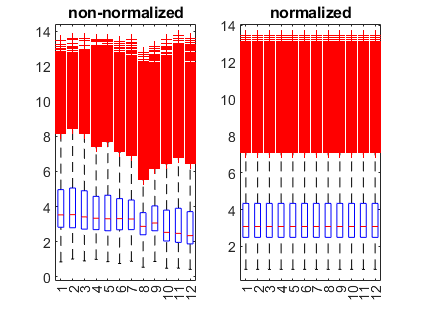

A = [t0 t8 t24 t32];
norm = quantilenorm(A);
figure
subplot(1,2,1); boxplot(A); title("non-normalized");
subplot(1,2,2); boxplot(norm); title("normalized");

  3. We need to make a vector with the timepoints for each sample to be able to quickly extract the right samples. For instance, if we had 2 samples taken every 2 hours, and they were in order in the table we would say time = [0, 0, 2, 2, 4, 4, 6, 6, 8, 8]; Then we could get just the 6 hour samples by saying data(:,time==6)  

Make a time vector which will work with the  you have generated from the normalised data.

time = [0 0 0 8 8 8 24 24 24 32 32 32];

       4. As this is microarray data, all genes will have been given a measurement even if there was no RNA from that gene present in the sample.  In these cases we will have a measurement for the luminesence of a black spot.  This means that we have two distributions of values, one of the expressed genes and one of the unexpressed genes.  In this example the unexpressed genes are the main peak, and are Gaussianly distributed.  The expressed genes look like a long tail of higher values on this peak.

        Make a histogram of all gene measurements, label these two distributions, and pick a cutoff point between them.  

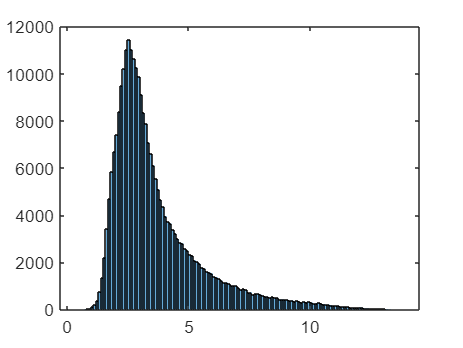

figure
histogram(A)

    5.  We now need to remove the unexpressed genes from the dataset.  But if a gene is expressed (has a value above your chosen cutoff) in all samples from a single timepoint, then it is interesting, even if it is unexpressed at other timepoints.

Find all the genes which are expressed in all samples of at least one timepoint.  How many are there?

cutoff = 3.5;                                       % select cutoff value
expr_idx = A(:,:) > cutoff;                         % gather indexes of values above cutoff point with logical values
mask = expr_idx(:, sum(expr_idx(1:12)) >= 3);       % filter rows where logical values 1 are more than 3 (all samples from 1 time point)
expressed_genes = A(mask,:)                         % finally retrieve original values for filtered indexes

expressed_genes =     6.5000    6.9019    6.5051    6.6443    6.9393    6.4321    6.1512    5.0792    6.0024    6.4035    6.4367    6.7563
   10.7186   10.8125   10.6017   10.2449   10.3308   10.1490    9.9075    8.6511    9.6767    9.3360    9.4661    9.2538
    5.1154    5.1743    5.2709    4.2735    4.4461    4.1532    3.7049    2.9265    3.5918    3.0225    3.1566    2.8956
    3.8909    4.1091    3.9231    3.4189    3.4333    2.8750    3.1158    2.3307    2.7968    2.7412    2.9620    2.5335
    4.0493    3.9038    3.7232    3.8880    3.7327    3.7398    3.7545    3.5168    3.5147    2.6830    2.7880    2.4645
    8.6781    8.6342    8.6910    8.0784    8.2527    7.8545    7.7370    6.7237    7.8686    7.3797    7.8877    7.4695
    7.3586    7.3985    7.2759    7.2538    7.2921    6.9355    6.4130    5.1929    6.4369    5.9708    6.2580    5.9034
    5.9769    5.9385    5.8270    6.2285    6.3443    6.1387    6.0859    4.6902    5.5119    6.4071    6.7218    6.8497
    3.7079    

6. We now want to find which of the expressed genes are differentially expressed after 8 hours.  In other words we are going to compare the samples at 0hrs with the samples at 8hrs and find the fold change and ttest p-value (fdr corrected)

        a. Calculate the log (base 2) fold change for each expressed gene between 0hrs and 8hrs.  Remember the values are log base 2, so the fold change will be calculated with subtraction.

et0 = expressed_genes(:,time==0);
et8 = expressed_genes(:,time==8);
fold_change = mean(et8,2) - mean(et0,2)

fold_change =     0.0362
   -0.4694
   -0.8959
   -0.7319
   -0.1052
   -0.6059
   -0.1839
    0.3230
   -0.2651
   -0.6849


        b. Calculate the p-value from a ttest (**ttest2)** for each expressed genes between 0hrs and 8hrs.

[H,P] = ttest2(et0.',et8.')

H =      0     1     1     1     0     1     0     1     0     1     0     1     1     1     0     0     1     0     0     1     1     0     0     1     1     1     1     1     1     0     1     0     1     1     1     0     1     1     1     1     1     0     1     1     1     1     1     0     1     1


P =     0.8639    0.0043    0.0007    0.0202    0.3813    0.0065    0.1962    0.0123    0.1260    0.0008    0.3053    0.0052    0.0301    0.0082    0.3029    0.0579    0.0317    0.0700    0.0841    0.0002    0.0143    0.1014    0.9849    0.0110    0.0047    0.0059    0.0479    0.0122    0.0022    0.0732    0.0002    0.8668    0.0087    0.0004    0.0100    0.3898    0.0288    0.0255    0.0437    0.0381    0.0102    0.9379    0.0075    0.0030    0.0002    0.0006    0.0003    0.7420    0.0019    0.0092


        c. Apply a muliple testing correction to your ttest p-values (**mafdr **with the BHFDR flag will do the Benjamini-Hochberg procedure we saw in the lecture).

fdr = mafdr(P,'bhfdr',1)

fdr =     0.8924    0.0174    0.0078    0.0455    0.4552    0.0219    0.2609    0.0328    0.1824    0.0080    0.3778    0.0191    0.0606    0.0251    0.3752    0.0987    0.0629    0.1142    0.1319    0.0049    0.0362    0.1528    0.9890    0.0303    0.0181    0.0206    0.0855    0.0325    0.0122    0.1183    0.0049    0.8944    0.0261    0.0063    0.0285    0.4629    0.0587    0.0536    0.0797    0.0723    0.0289    0.9525    0.0239    0.0141    0.0054    0.0069    0.0059    0.7881    0.0112    0.0271


        d. How many genes have both a log base 2 fold change >1 if upregulated or <-1 if downregulated (why these values?) and a significant (<0.05) p-value after correction?

fdr = fdr.';
G = (fold_change > 1 | fold_change < -1) & fdr < 0.05;
x = sum(G)

x = 1118

p = x/n

p = 0.0492

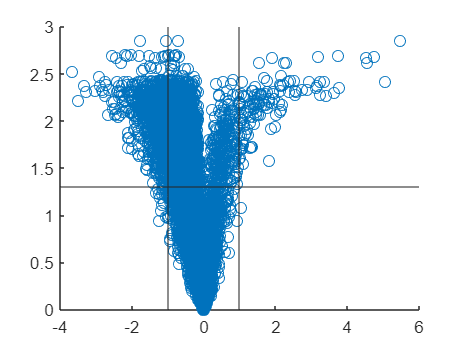

figure;
hold on;
scatter(fold_change, -log10(fdr));
xline(-1,'-'); xline(1,'-'); yline(-log10(0.05));

**Assignment**

Some toxicology researchers want to know the effect of Cyclosporin A (CSA) on human cells. They take two doses of this compound (20uM and 3uM) and take samples after 12, 24, 48 and 72 hours of exposure. They also take samples from cells exposed to just the solvent which the CSA is normally dissolved into, DMSO (eg the samples labelled DMSO are untreated and the samples labelled CSA are treated). They want to know which genes are affected by the CSA.  

- After preprocessing (as above) pick at least one dose/timepoint combination and find the differentially expressed genes.

The data for this task is in the file raw_data_labelled.csv the rows are labelled with the affymetrix id of the probe - there will be many probes measuring each gene.  